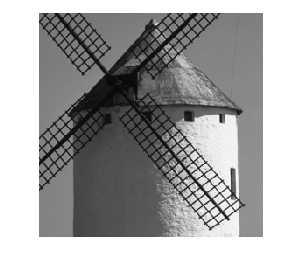

%imwrite(b11, ’b11.tif’, ’Resolution’, 150);
%Kommandot sparar bilden med upplösningen 150 dots (eller pixlar)/tum 
% i tif format
clear;
kvarn = imread('kvarn.tif');
kvarn = im2double(kvarn);
imshow(kvarn);

% 1.1 
b11 = (kvarn >= 0.5)

b11 = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

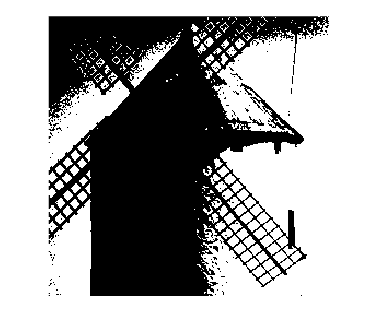

imshow(b11)

imwrite(b11, 'b11.tif', 'Resolution', 150);

% 1.2
load('troskelmatriser.mat')
tr1 = tr1/19

tr1 =     0.4737    0.3684    0.4211    0.5263    0.6316    0.5789
    0.3158    0.0526    0.1053    0.6842    0.9474    0.8947
    0.2632    0.2105    0.1579    0.7368    0.7895    0.8421
    0.5263    0.6316    0.5789    0.4737    0.3684    0.4211
    0.6842    0.9474    0.8947    0.3158    0.0526    0.1053
    0.7368    0.7895    0.8421    0.2632    0.2105    0.1579


tr2 = tr2/33

tr2 =     0.4242    0.3636    0.3939    0.4848    0.5758    0.6364    0.6061    0.5152
    0.1515    0.1212    0.0909    0.3030    0.8485    0.8788    0.9091    0.6970
    0.1818    0.0303    0.0606    0.3333    0.8182    0.9697    0.9394    0.6667
    0.2727    0.2121    0.2424    0.4545    0.7273    0.7879    0.7576    0.5455
    0.5758    0.6364    0.6061    0.5152    0.4242    0.3636    0.3939    0.4848
    0.8485    0.8788    0.9091    0.6970    0.1515    0.1212    0.0909    0.3030
    0.8182    0.9697    0.9394    0.6667    0.1818    0.0303    0.0606    0.3333
    0.7273    0.7879    0.7576    0.5455    0.2727    0.2121    0.2424    0.4545


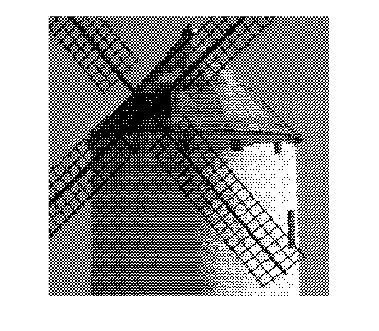

b12_tr1 = troskel(kvarn, tr1);
imshow(b12_tr1)

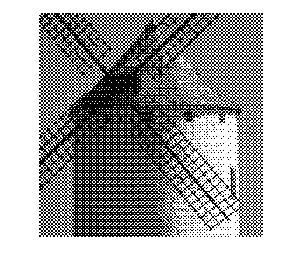

b12_tr2 = troskel(kvarn, tr2);
imshow(b12_tr2)

imwrite(b12_tr1, 'b12_tr1.tif', 'Resolution', 150);
imwrite(b12_tr2, 'b12_tr2.tif', 'Resolution', 150);

% 1.3
tr3 = tr3/33

tr3 =     0.0303    0.9091    0.2424    0.8485    0.0606    0.8788    0.2121    0.8182
    0.5152    0.2727    0.7273    0.4848    0.5455    0.3030    0.6970    0.4545
    0.1515    0.7576    0.0909    0.9697    0.1818    0.7879    0.1212    0.9394
    0.6364    0.3939    0.5758    0.3333    0.6667    0.4242    0.6061    0.3636
    0.0606    0.8788    0.2121    0.8182    0.0303    0.9091    0.2424    0.8485
    0.5455    0.3030    0.6970    0.4545    0.5152    0.2727    0.7273    0.4848
    0.1818    0.7879    0.1212    0.9394    0.1515    0.7576    0.0909    0.9697
    0.6667    0.4242    0.6061    0.3636    0.6364    0.3939    0.5758    0.3333


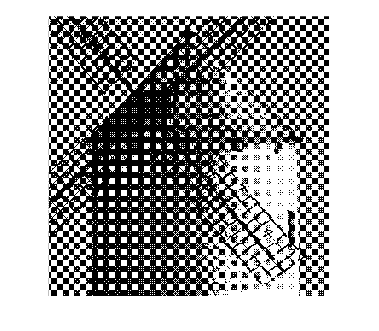

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.



b13 = troskel(kvarn, tr3);
imshow(b13)

imwrite(b13, 'b13.tif', 'Resolution', 150);

% 1.4
linje = [1, 2, 3, 4;
    5, 6, 7, 8;
    9, 10, 11, 12;
    13, 14, 15, 16]/17;
spiral = [10, 9, 8, 7;
        11, 2, 1, 6;
        12, 3, 4, 5;
        13, 14, 15, 16] / 17;

b14_linje = troskel(kvarn, linje)

b14_linje = 512×512 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1   1   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   1   0   0   0   1   1   1   1   1   1
   1   1   1   0   1   1   1   0   1   0   0   0   1   0   0   0   0   0   0   0   1   0   1   0   1   1   1   0   1   1   1   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0  

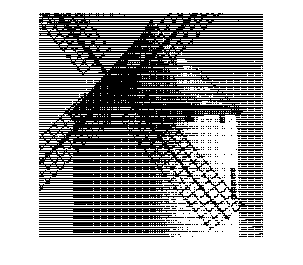

imshow(b14_linje)

imwrite(b14_linje, 'b14_linje.tif', 'Resolution', 150);

b14_spiral = troskel(kvarn, spiral)

b14_spiral = 512×512 logical array
   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0
   0   1   1   1   0   1   1   1   0   1   1   0   0   1   1   1   0   1   1   0   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   0   0   0   1   0   0   0   1   0   0   1   1   1   0   1
   0   1   1   1   0   1   1   1   0   1   1   0   0   0   0   0   0   0   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   0   0   0   0   0   0   0   0   0   1   0   0   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0 

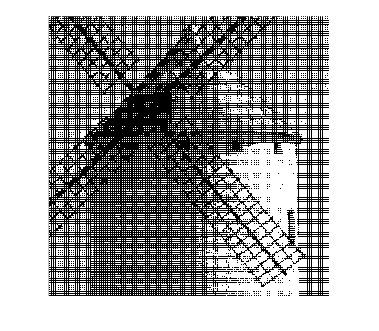

imshow(b14_spiral)

imwrite(b14_spiral, 'b14_spiral.tif', 'Resolution', 150);

% 2.1
b21 = tabellrast(kvarn)

b21 = 512×512 logical array
   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0
   1   1   1   0   1   1   1   0   0   1   1   0   0   1   1   0   0   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   0   1   0   0   0   1   0   0   0   1   1   0   1   1
   1   1   1   0   1   1   1   0   0   1   1   0   0   0   1   0   0   0   1   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   0   0   0   0   0   0   0   0   0   1   1   0   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0

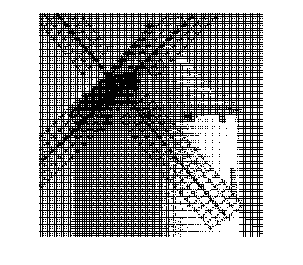

imshow(b21)

imwrite(b21, 'b21.tif', 'Resolution', 150);

% 2.2
b22 = tabellrast2(kvarn)

b22 = 512×512 logical array
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   1   0   1   0
   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   1   0   1   0   1   0
   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0

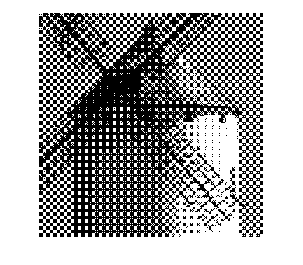

imshow(b22)

imwrite(b22, 'b22.tif', 'Resolution', 150);

% 2.3
b24 = tabellrast3(kvarn)

b24 = 1024×1024 logical array
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0
   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   1   0   1
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0
   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   1   0   1  

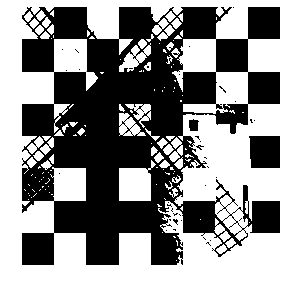

imshow(b24)

imwrite(b24, 'b24.tif', 'Resolution', 150);
whos b24

  Name         Size                Bytes  Class      Attributes

  b24       1024x1024            1048576  logical              



% 3.1
filt1 = [0 0 7;
        3 5 1]/16;
b31 = errordif(kvarn, filt1)

b31 =      0     1     0     1     0     1     0     1     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0
     1     0     1     0     1     0     0     1     0     1     0     0     1     0     0     1     0     0     0     1     0     0     1     0     1     0     1     0     1     0     1     0     1     0     0     1     0     0     0     0     0     0     0     0     1     0     0     1     0     1
     0     1     0     0     1     0     1     0     1     0     0     0     0     0     0     0     0     1     0     0     1     0     1     0     0     1     0     0     1     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     1     0     1     0     1     0     1     0     1     0     1     0     0     0 

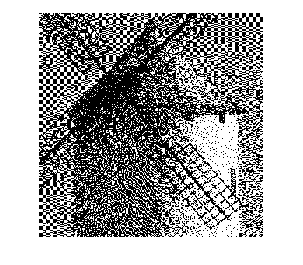

imshow(b31)

imwrite(b31, 'b31.tif', 'Resolution', 150);

% 3.2
filt2 =  [0 0 0 7 5;
        3 5 7 5 3;
        1 3 5 3 1]/48;
b32 = errordif(kvarn, filt2)

b32 =      0     1     0     0     1     0     0     1     0     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     0     1     0     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     1     0     1     0     1     1     0     1     0     0     0     0     1     0     1     0     0     0     0     0     1     0     1     1     0     1     1     0     1     1     0     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     1
     0     1     0     0     1     0     0     1     1     0     0     0     0     0     0     0     0     0     1     0     1     0     0     1     0     0     1     0     0     1     0     0     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     1     0     1     0     0     1     0     1     1     0     0     0     0     0 

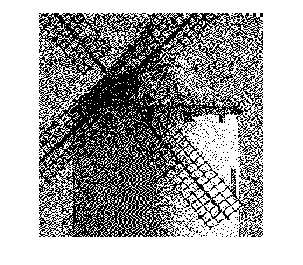

imshow(b32)

imwrite(b32, 'b32.tif', 'Resolution', 150);

% 3.4
filt3 = [0;
        1];
filt4 = [0 0 1;
        0 1 0]/2;

b34_f3 = errordif(kvarn, filt3)

b34_f3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     0     0     1     1     1     1     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     1     1     0     0     0     0
     1     1     1     1     1     1     1     1     0     0     1     1     0     0    

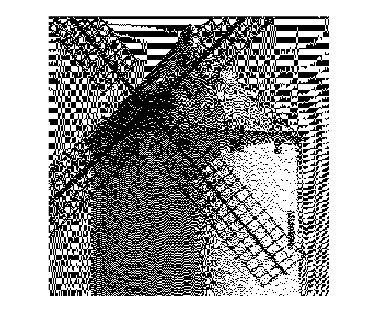

imshow(b34_f3)

imwrite(b34_f3, 'b34_f3.tif', 'Resolution', 150);

b34_f4 = errordif(kvarn, filt4)

b34_f4 =      0     1     0     1     0     1     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0
     1     0     1     0     1     0     1     0     0     1     0     0     1     0     0     1     0     1     0     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     0     1     0     0     0     0     0     0     0     0     1     0     0     1     0     1
     0     1     0     1     0     1     0     0     1     0     0     1     0     0     0     0     0     0     0     1     0     1     0     1     0     1     0     0     1     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     1     0     1     0     0     0     1     1     0     1     0     0     0     0    

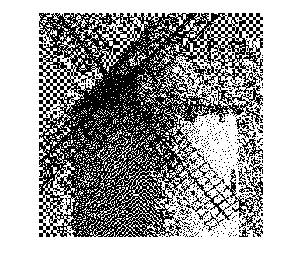

imshow(b34_f4)

imwrite(b34_f4, 'b34_f4.tif', 'Resolution', 150);

% 3.6
k = 0.4

k = 0.4000

noise = (rand(512, 512) - 0.5) * k

noise =    -0.0092    0.0359   -0.1255    0.0081    0.0661   -0.1637    0.0709    0.1041   -0.1660    0.0933   -0.0156   -0.0904    0.0670    0.0148   -0.1418   -0.0797    0.0998   -0.0441    0.1080    0.0852    0.1408   -0.0420   -0.0228    0.1367    0.1556    0.1660   -0.0641   -0.0317    0.1356    0.0264    0.1198    0.1532   -0.1252   -0.0661    0.1671    0.0725    0.0058   -0.0937    0.1384    0.1024    0.0755   -0.0553    0.0258    0.1754    0.0397   -0.0308   -0.0148    0.0417   -0.0112   -0.0502
   -0.1468   -0.0440   -0.1576    0.1272   -0.1842    0.0066    0.1041   -0.1867    0.1663    0.1988    0.1766   -0.1959   -0.1984   -0.1922    0.0770   -0.1158   -0.1433   -0.1377   -0.1049   -0.1016    0.1798   -0.0353    0.1717    0.0612    0.0439   -0.0472   -0.0049    0.0598   -0.0300   -0.0052    0.1185    0.1243    0.0344    0.0384   -0.0668   -0.1815   -0.0210   -0.0754    0.0569    0.0796   -0.0541    0.1392   -0.0596    0.0144   -0.1364    0.0174   -0.0049    0.0034   -0.0625 

b36 = kvarn + noise

b36 =     0.4496    0.4947    0.3294    0.4630    0.5210    0.2912    0.5179    0.5512    0.1321    0.3914    0.0864    0.0116    0.3611    0.3089    0.2660    0.3282    0.2841    0.1402    0.2335    0.2107    0.4859    0.3031    0.4360    0.5955    0.6144    0.6248    0.3947    0.4272    0.5905    0.4813    0.5787    0.6120    0.3376    0.3966    0.4024    0.3078    0.0764   -0.0231    0.2050    0.1690    0.1382    0.0074    0.1082    0.2578    0.2633    0.1927    0.4048    0.4613    0.4476    0.4086
    0.3120    0.4148    0.2973    0.5821    0.2707    0.4615    0.5512    0.2603    0.4644    0.4968    0.2786   -0.0940    0.0958    0.1019    0.4848    0.2920    0.0410    0.0466    0.0206    0.0239    0.5249    0.3097    0.6305    0.5200    0.5028    0.4117    0.4539    0.5187    0.4249    0.4497    0.5773    0.5831    0.4972    0.5011    0.1685    0.0538    0.0496   -0.0048    0.1236    0.1463    0.0086    0.2019    0.0228    0.0967    0.0871    0.2409    0.4147    0.4230    0.3963   

b36 = errordif(b36, filt1)

b36 =      0     1     0     1     0     0     1     0     0     1     0     0     0     0     0     1     0     0     0     0     1     0     0     1     1     0     1     0     1     0     1     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     1     0     1     0
     0     1     0     1     0     1     0     1     0     0     0     0     0     1     0     0     0     0     0     0     1     0     1     0     1     0     1     0     1     0     1     1     0     1     0     0     0     0     0     0     0     0     0     0     0     1     0     0     1     0
     0     0     0     0     1     0     1     0     1     0     1     0     0     0     0     0     0     0     1     0     1     0     1     0     1     0     0     1     0     1     0     1     0     1     0     0     0     0     0     0     1     0     0     0     0     0     1     0     0     1
     1     1     0     1     1     0     1     0     1     0     0     0     0     0     0 

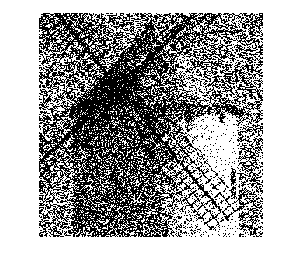

imshow(b36)

imwrite(b36, 'b36.tif', 'Resolution', 150);

% 4
b40 = imcdp(kvarn)

imcdp
----------
here13
here14
here14
9% done
----
17% done
----
26% done
----
34% done
----
34% done
----
43% done
----
52% done
----
60% done
----
69% done
----
78% done
----
86% done
----
95% done
----
here9
here1
here15
here8
here7
here5
here17
here10
here6
here18
here3
here16
here4
here11
here2
here12


b40 =      0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     0     1     0     1     1     1     0     1     1     1     1     0     1     1     0     0
     0     0     1     0     1     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0     0     1     1     0     1     1     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1
     0     1     1     0     0     1     1     0     1     0     0     0     0     0     0     0     0     0     1     0     0     0     1     1     1     0     0     0     1     0     1     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     1     0     0     1
     0     1     0     1     1     0     0     0     0     1     1     0     1     0     0 

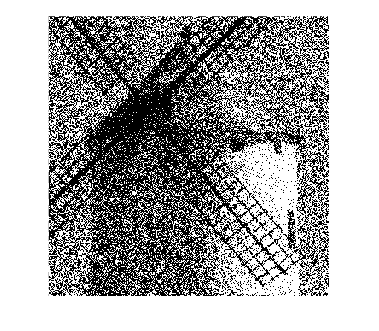

imshow(b40)

imwrite(b40, 'b40.tif', 'Resolution', 150);

% 5.1
SNRb11 = mysnr(kvarn, kvarn - b11)

SNRb11 = 2.5915

SNRb31 = mysnr(kvarn, kvarn - b31)

SNRb31 = 0.8801

SNRb40 = mysnr(kvarn, kvarn - b40)

SNRb40 = 0.8080

% 5.2
SNRfilterb11 = snr_filter(kvarn, kvarn - b11)

SNRfilterb11 = 2.9988

SNRfilterb31 = snr_filter(kvarn, kvarn - b31)

SNRfilterb31 = 13.9621

SNRfilterb40 = snr_filter(kvarn, kvarn - b40)

SNRfilterb40 = 12.0072

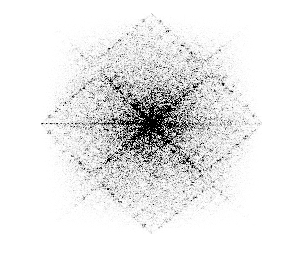

% 5.3
QNSb11 = QNS(kvarn, b11);

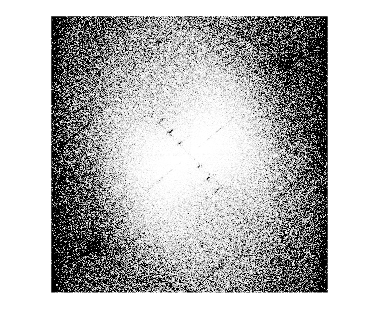

QNSb31 = QNS(kvarn, b31);

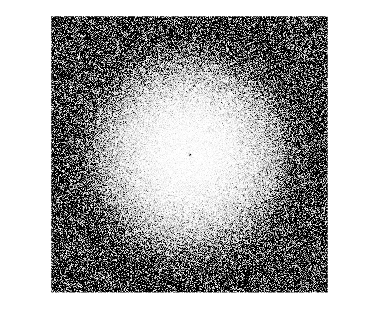

QNSb40 = QNS(kvarn, b40);

imwrite(QNSb11, 'QNSb11.tif', 'Resolution', 150);
imwrite(QNSb31, 'QNSb31.tif', 'Resolution', 150);
imwrite(QNSb40, 'QNSb40.tif', 'Resolution', 150);

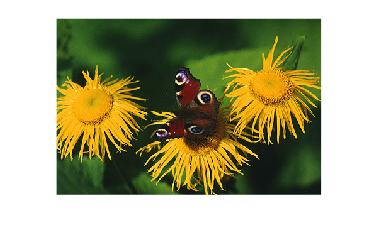

% Del 3
musicians = im2double(imread('musicians.tif'));
butter = im2double(imread('butterfly.tif'));

imshow(butter)

imgButter = fargraster(butter, 'imcdp');

imcdp
----------
23% done
----
47% done
----
here14
here14
70% done
----
here13
here12
94% done
----
here11
here4
here16
here8
here9
here7
here15
here17
here3
here18
here5
here10
here2
here6
here1
imcdp
----------
here14
24% done
----
here16
48% done
----
here14
here12
here13
72% done
----
here11
96% done
----
here18
here10
here9
here8
here5
here7
here6
here4
here3
here2
here15
here1
here17
imcdp
----------
here15
here16
here17
here3
here4
here2
here14
here7
88% done
----
here6
here8
here9
here14
here10
here13
here11
here12
here5
here18
here1


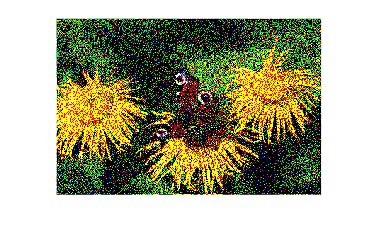

imshow(imgButter)

imgButter = fargraster(butter, 'majs');

Måste använda errordif eller IMCDP


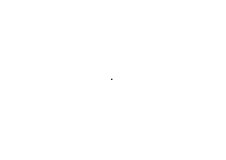

imshow(imgButter)

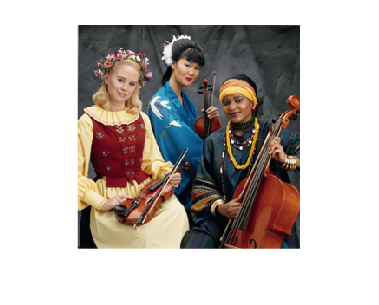


imshow(musicians)

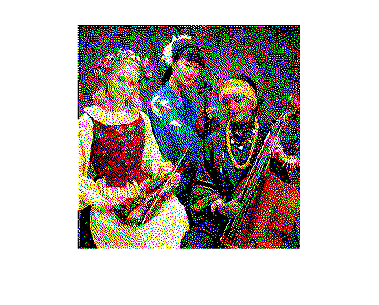

imgMusic = fargraster(musicians, 'errordif');
imshow(imgMusic)